# Classical Simulation

We must also rule out the possibility of this system acting classically.  A classical beam splitter that doesn't work perfectly may possibly produce results that look quantum so we will want to rule this out as a possibility.  We will consider beam splitters at each end with unique biases towards the northern spheres:

## Parameters:

- $\lambda$ = L - mode occupancy.  

- $\phi$ - phase of interferometer.  

- $T_{max}$ - maximum number of generated particle

- cycles = C - number of simulated tests used to perform correlation.

- QE = R - retention rate / quantum efficiency.

- dark_rate = D - fraction of tests which return a non-experimental count.

- $\sigma$ = B - decay width of gaussian blur in detection uncertainty.

- phys - Quantum ('Q') or Classical ('C') physics to be used.

- $Y_{\text{bias}}$ - with a classical beam splitter, the R.H.S. bias towards Y (up)

- $X_{\text{bias}}$ -         "             "                      , the L.H.S. bias towards X (up)

lambda = 0.1;
% phi =   ;
Tmax = 8;
cycles = 2E4;
QE = 100;
dark_rate = 0;
sigma = 0;
phys = 'C';

## Arrays:

Ybias = 0:0.1:1;
Xbias = 0:0.1:1;
phi = 0:pi/3:pi;

g_same = zeros(length(Ybias),length(Xbias),length(phi));
g_opp = g_same;

percent = 9.0909

percent = 18.1818

percent = 27.2727

percent = 36.3636

percent = 45.4545

percent = 54.5455

percent = 63.6364

percent = 72.7273

percent = 81.8182

percent = 90.9091

percent = 100

percent = 25

percent = 9.0909

percent = 18.1818

percent = 27.2727

percent = 36.3636

percent = 45.4545

percent = 54.5455

percent = 63.6364

percent = 72.7273

percent = 81.8182

percent = 90.9091

percent = 100

percent = 50

percent = 9.0909

percent = 18.1818

percent = 27.2727

percent = 36.3636

percent = 45.4545

percent = 54.5455

percent = 63.6364

percent = 72.7273

percent = 81.8182

percent = 90.9091

percent = 100

percent = 75

percent = 9.0909

percent = 18.1818

percent = 27.2727

percent = 36.3636

percent = 45.4545

percent = 54.5455

percent = 63.6364

percent = 72.7273

percent = 81.8182

percent = 90.9091

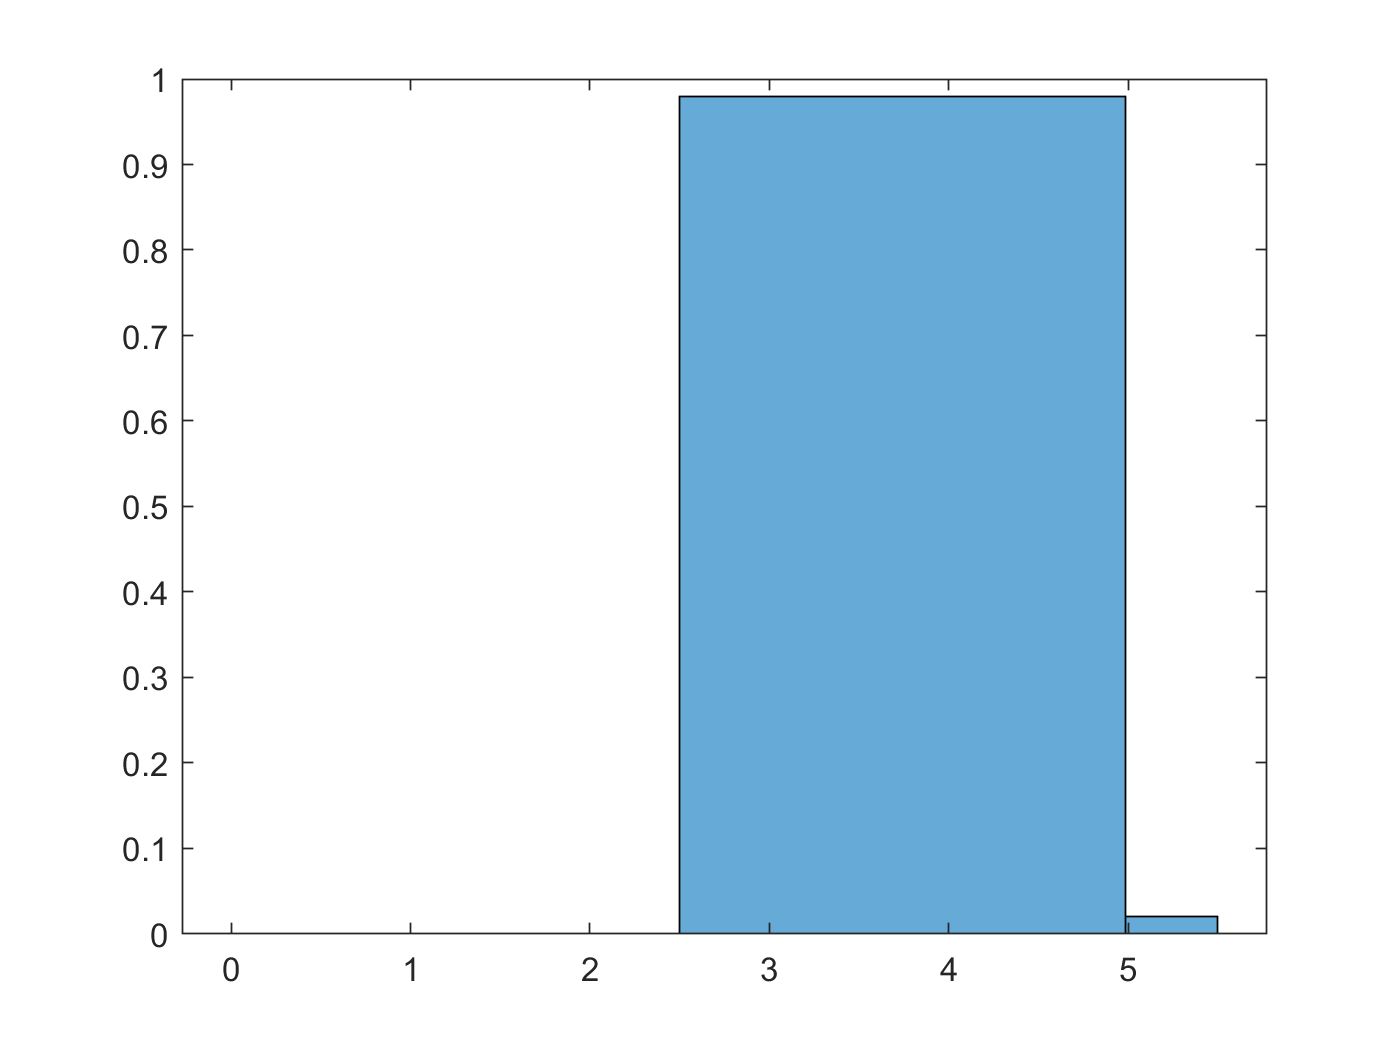

percent = 100

percent = 100

for p = 1:length(phi)
    for y = 1:length(Ybias)
        for x = 1:length(Xbias)
            [g_side, g_diag,~,~,~] = correlators2(lambda,phi(p),Tmax,cycles,QE,dark_rate,sigma,0.3,phys,Ybias(y),Xbias(x));
            g_same(y,x,p) = g_side;
            g_opp(y,x,p) = g_diag;
        end
        percent = 100*y/length(Ybias)
    end
    percent = 100*p/length(phi)
end

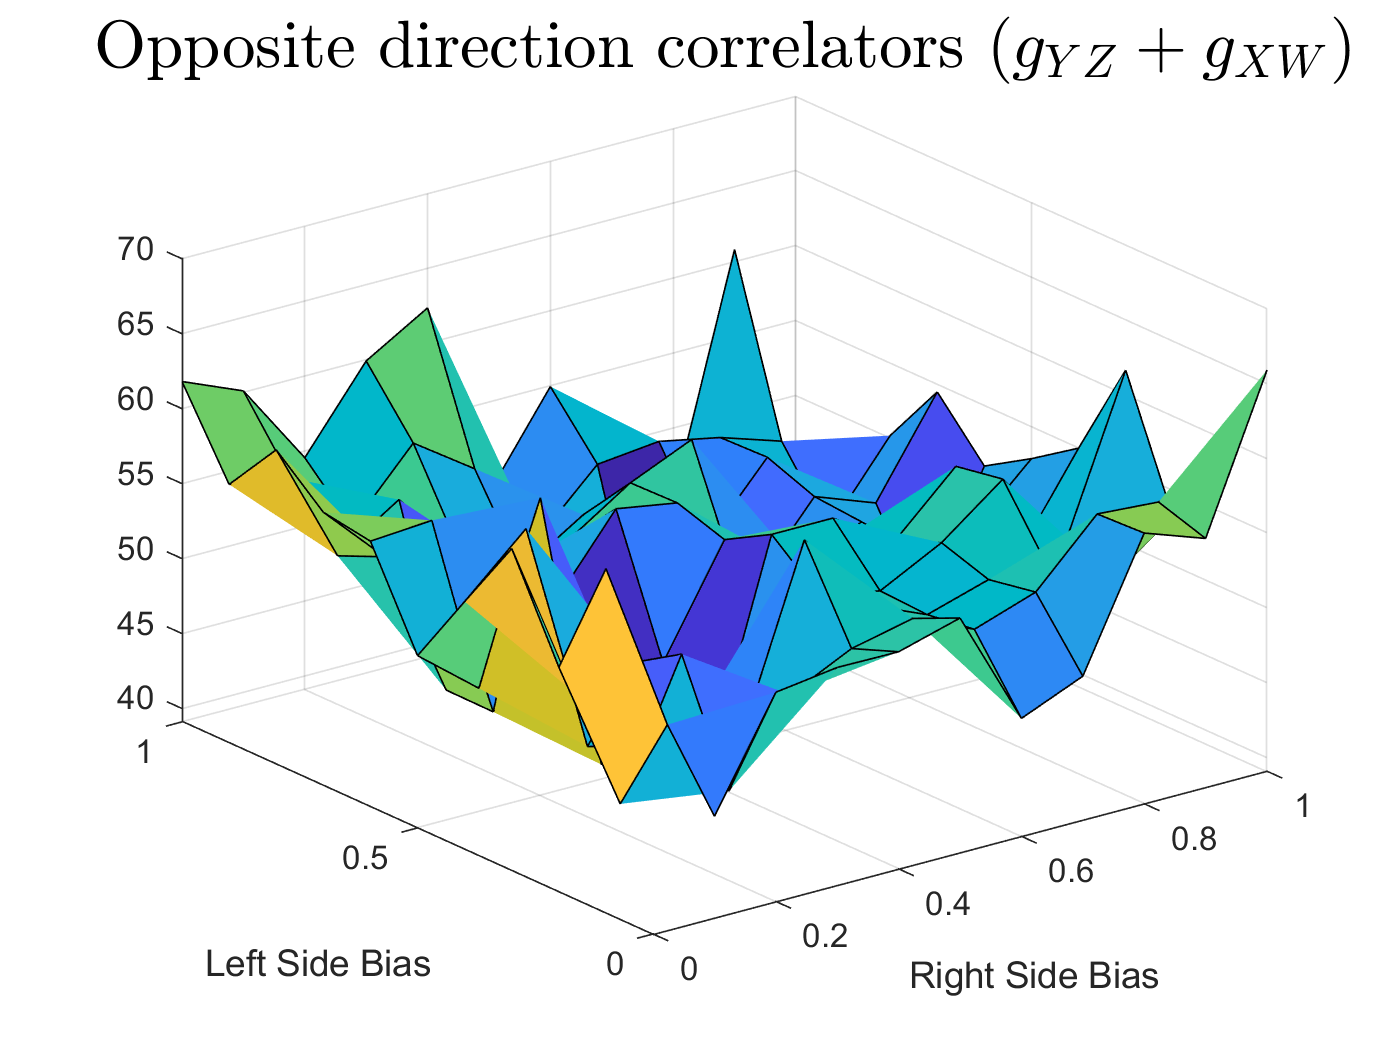

p =1;
figure(1);
clf();
surf(Ybias,Xbias,g_opp(:,:,p))
xlabel("Right Side Bias")
ylabel("Left Side Bias")
title("Opposite direction correlators ($g_{YZ} + g_{XW}$)",'interpreter','latex',"FontSize",20)